# Геометрия и статистика

## Основные понятия в математической статистике

- Population (Популяция), генеральная совокупность

- Сумма, средние значения, вариация (дисперсия) 

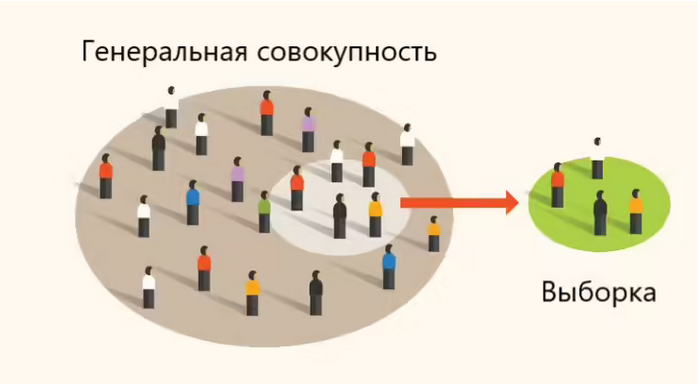

**Генеральная совокупность может быть конечная или бесконечная**

**конечный размер генеральной совокупности - число жителей в Москве**

**бесконечная генеральная совокупность - физические измерения**

**Основная идея - рассматривать генеральную совокупность и выборки как вектора**

**Допустим наша генеральная совокупность состоит из N элементов, следовательно вектор будет выглядеть следующим образом**


$$\vec{x}= [x_1,x_2,...x_N]$$


**Допустим у нас есть некая выборка (измерения физических величин). Каждое измерение физической величины можно записать в виде координаты вектора**

$\vec{x} = [x_1, x_2, ..., x_{k}]$ (не обязательно по порядку)

$k \le N$ (РАЗМЕРНОСТЬ ВЫБОРКИ ВСЕГДА НИЖЕ РАЗМЕРНОСТИ ГЕНЕРАЛЬНОЙ СОВОКУПНОСТИ)

**Основные понятия мы тоже можем выразить через вектора **

### **Сумма**


$$\Sigma_1^Nx_i = x_1 +x_2+ ...+x_N$$


Нам понадобится вектор, состоящий из единиц и имеющий такую же размерность, что и наш вектор выборки 


$$\vec{I} = [1,1,...,1]$$


Сумму можно найти с помощью скалярного произведения


$$\Sigma_1^Nx_i = (\vec{x} \cdot \vec{I}) = x_1\cdot 1+x_2\cdot1+ ...x_N \cdot1$$


### Среднее значение

$( \vec{I} \cdot \vec{I^T})^{-1} $ - Скалярное произведение единичных векторов даст нам размерность пространства, минус первая степень даст нам $\frac{1}{N}$ (или $\frac{1}{k}$ для выборки) 

$\mu =  \frac{\Sigma_1^Nx_i }{N} = (\vec{x} \cdot \vec{I}) \cdot ( \vec{I} \cdot \vec{I^T})^{-1}$ - для генеральной совокупности 

$\bar{x}=  \frac{\Sigma_1^{k}x_i }{k} = (\vec{x} \cdot \vec{I}) \cdot ( \vec{I} \cdot \vec{I^T})^{-1}$ - для выборки (считается одинаково)

### Вариация

Вариацию (дисперсию) можно записать следующим образом


$$\sigma^2 = \Sigma_1^N  \frac{(x_i-\bar{x})}{N}=  \frac{(\vec{x} -  \bar{x} )^2}{N}
$$



$$\sigma =\Sigma_1^N  \frac{(x_i-\bar{x})}{N}=  \frac{ ||(\vec{x}-\bar{x})||  } { \sqrt{N}}$$


## Визуализация

Попробуем применить данные концепции и построить вектора генеральной совокупности и вектора выборок 

Для начала рассмотрим двумерный вариант (за один эксперимент мы проводим всего два измерения) с большой генеральной совокупностью 

clearvars
s = rng(1)

s = struct with fields:
     Type: 'twister'
     Seed: 1
    State: [625×1 uint32]


% Сгенерируем генеральную совокупность вокруг некоторого среднего значения      
mu = 5; % предполагаемое мат ожидание
size_of_population = 8204

size_of_population = 8204

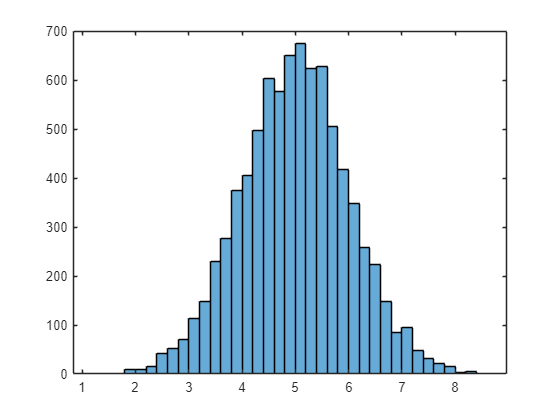

population = randn(1,size_of_population)'+mu; % создаем вектор из нормального распределения, смещаем его на mu
histogram(population)
hold off


% достанем из генеральной совокупности выборки 
x = zeros(1,2);

disp("Сколько выборок мы рассматриваем")

Сколько выборок мы рассматриваем


N = 22

N = 22

for i = 1:N
    x(i,:) = randsample(population,2);
end
x = x';

% вектор средних значений выборки 
mean_x = zeros(2,N);

for i = 1:N
    mean_x(:,i) = mean(x(:,i))*ones(2,1);
end

% вектор вариации
x_Ex = x-mean_x;
X = cell(1, N);
[X{:}] = extract(x_Ex); % ВЕКТОР ОШИБОК


ax = draw_vector([],'заголовок',['выборки'], 'point',x);
ax = draw_vector([ax],'заголовок',['выборки'], 'point',mean_x);
ax = draw_vector([ax],'двумерные выборки',['выборки'], 'vector',[mu,mu]);

ax = draw_vector([ax],'заголовок',['выборки'], 'vector', X{:});
legend('off')
title('')
ax.XLim = [-2,8];
ax.YLim = [-2,8];
hold off


Ограничимся размерностью генеральной совокупности равной трем (N = 3)

Размер выборки равен 2 (k =2)

clearvars
% Сгенерируем генеральную совокупность вокруг некоторого среднего значения      
mu = 5;
population = randn(1,3)'+mu; % создаем вектор из нормального распределения, смещаем его на mu
disp("Генеральная совокупность")

Генеральная совокупность


disp(population)

    4.8940
    4.2455
    4.5570



% достанем из генеральной совокупности выборки 
x = zeros(1,2);
disp("Сколько выборок мы рассматриваем")

Сколько выборок мы рассматриваем


N = 6

N = 6

for i = 1:N
    x(i,:) = randsample(population,2);
end
x = x';
% вектор средних значений выборки 
mean_x = zeros(2,N)

mean_x =      0     0     0     0     0     0
     0     0     0     0     0     0



for i = 1:N
    mean_x(:,i) = mean(x(:,i))*ones(2,1);
end

% вектор вариации
x_Ex = mean_x-x

x_Ex =    -0.3242    0.1685   -0.3242   -0.3242   -0.3242   -0.3242
    0.3242   -0.1685    0.3242    0.3242    0.3242    0.3242


X = cell(1, N);
[X{:}] = extract(x_Ex); % ВЕКТОР ОШИБОК

% нарисуем вектора

ax = draw_vector([],'генеральная совокупность и выборки',['вектора в 3д'], 'vector',population,mean(population)*ones(1,3));

ax = draw_vector([ax],'генеральная совокупность и выборки',['выборки'], 'point',x);
ax = draw_vector([ax],'генеральная совокупность и выборки',['выборки'], 'point',mean_x);
ax = draw_vector([ax],'генеральная совокупность и выборки',['variance'], 'vector',X{:});



hold(ax,"on");
ax.XLim = [-8,8];
ax.YLim = [-8,8];
ax.ZLim = [-8,8];

clearvars
% % s = rng(1)
N = 50;
Population = randn(1,N*10)'+1;



% fill sample matrix
vectors = zeros(N,3);
for i = 1:N
    vectors(i,:) = randsample(Population,3);
end
vectors = vectors';

%fill mean sample matrix
vectors_mean = zeros(N,3);
for i = 1:N
    vectors_mean(i,:) = mean(vectors(:,i))*ones(1,3);
end
vectors_mean = vectors_mean';

%fill sample - mean_sample matrix
v_Ev = vectors - vectors_mean;



X = cell(1, N);
[X{:}] = extract(v_Ev); % ВЕКТОР ОШИБОК
ax = draw_vector([],'title','variance', 'vector',X{:});

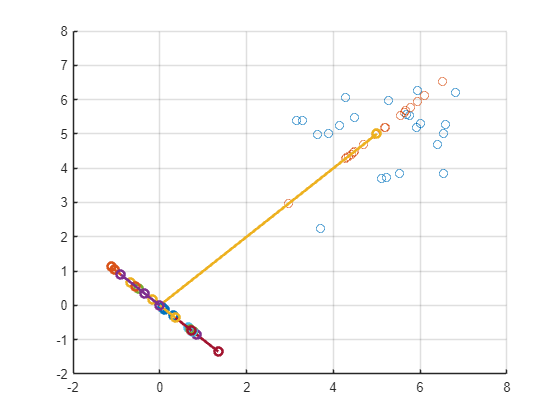


hold(ax,"on");
ax = draw_vector([ax],'title','vectors', 'point',vectors);

ax = draw_vector(ax,'title','vectors', 'vector',mean(Population)*ones(1,3));

ax = draw_vector(ax,'title','vectors', 'point',vectors_mean);
ax.XLim = [-6,6];
ax.YLim = [-6,6];
ax.ZLim = [-6,6];


function [varargout] = extract(A)
    for i = 1:length(A)
        varargout{i} = A(:,i);
    end
end



function [bpar,bper,ang] = projection_matrix(A,b)
% функция считает угол между вектором и пространством столбцов матрицы A
    for ii =1:size(A,2)
        A(:,ii) = A(:,ii)/norm(A(:,ii));
    end
    beta = A*transpose(A)*b;
    beta = beta/norm(beta); % нормируем вектор beta
    Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
    bpar = Pbeta*b;
    bper = b-bpar;
    ang = rad2deg(acos(norm(bpar)/norm(b)));
end

function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = size(varargin{1},1)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function [new_ax,fig_handle] = get_next_ax(index, axes_name_value_pairs)
% функция, которая возвращает новые оси на новой фигуре (нужна чтобы
% кратинки в ливскрипте нормально строились)
    arguments
        index = []
        axes_name_value_pairs cell = {}
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);        
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});
        %disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});    
    end
end